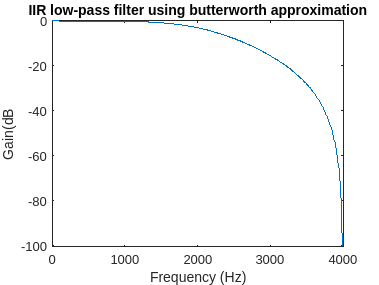

close all;clear;clc;
fm=1000;
fs=8000;
t=0:1/fs:10/fm;
signal=0.5*sin(2*pi*fm*t);
noise_comp1=0.5*sin(2*pi*3400*t);
noise_comp2=0.5*sin(2*pi*3600*t);
noise_comp3=0.5*sin(2*pi*3800*t);
noise=noise_comp1+noise_comp2+noise_comp3;
noisy_signal=signal+noise;
N=1024; %for DFT 

f1=1500;
f2=2000;
k1=-1;
k2=-3;
%we can take all the input from the user for all 4 above

k=0:(N/2-1);
f=k*(fs/N);
 %specification
w1=2*pi*f1*1/fs;
w2=2*pi*f2*1/fs;

%pre warping
o1=2*fs*tan(w1/2);
o2=2*fs*tan(w2/2);

%design of analog filter

[n,wn]=buttord(o1,o2,k1,k2,'s');
[num,den]=butter(n,wn,'s');

%converting analog to digital filter
[numz,denz]=bilinear(num,den,fs);
w=2*pi*f/fs;
h=freqz(numz,denz,w);
gain1=20*log10(abs(h));

plot(f,gain1),xlabel('Frequency (Hz)');ylabel('Gain(dB');
title('IIR low-pass filter using butterworth approximation');
axis([0 fs/2 -inf 0]);

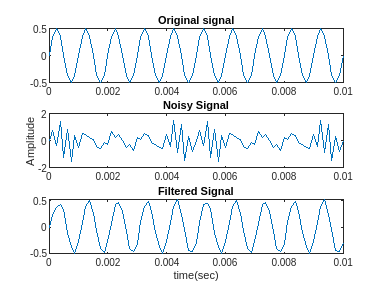


%Filter the noisy signal using the designed filter 
filtered_signal=filter(numz,denz,noisy_signal);

%plot original ,noisy and filtered signal
figure(2);
subplot(311),plot(t,signal);
title('Original signal');
subplot(312),plot(t,noisy_signal);
title('Noisy Signal');
ylabel('Amplitude');
subplot(313),plot(t,filtered_signal);
title('Filtered Signal');
xlabel('time(sec)');

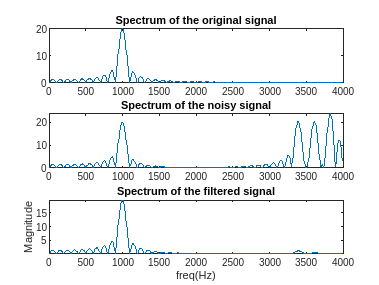


%computer the fft of the original noisy and filtered signal
fft1=abs(fft(signal,N));
fft2=abs(fft(noisy_signal,N));
fft3=abs(fft(filtered_signal,N));

%plot the spectrum of the original , noisy and the filtered signal 
figure(3);
title('IIR LPF using Butterworth approximation');
subplot(311),plot(f,fft1(1:N/2));
title('Spectrum of the original signal');
subplot(312),plot(f,fft2(1:N/2));
title('Spectrum of the noisy signal');
subplot(313),plot(f,fft3(1:N/2));
title('Spectrum of the filtered signal');
ylabel('Magnitude');
xlabel('freq(Hz)')
axis([0 fs/2 -inf inf]);w1 = 2 * fs * tan(w1/2);